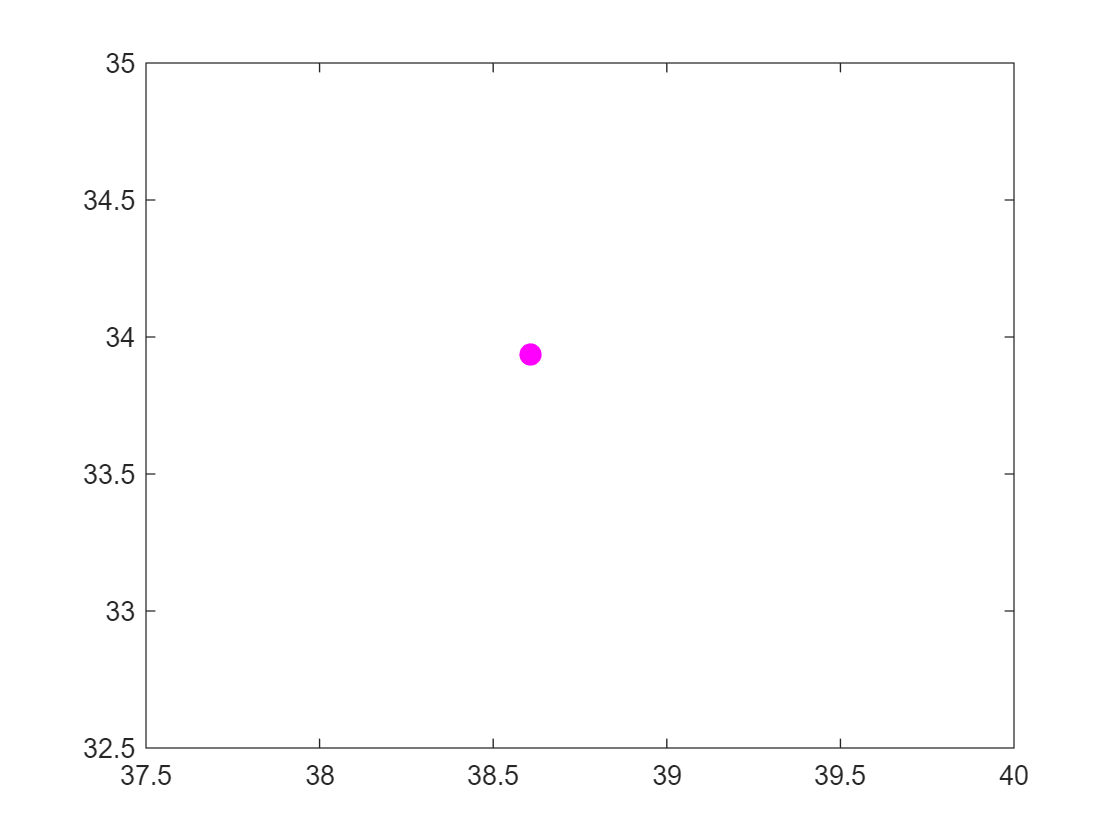

clear all
%% 定义函数输入
Start_Point = [0,0,pi/2];
End_Point = [100,30,pi*3/4];
r=5;
R=18;
Stepsize=0.1;
Avoid_Center = [50,20];


titles = {'RSR-LR', 'RSL-SL', 'LSL-LSL', 'LSR-SR'};
%% 寻找Dubins路径
param = Dubins_obs(Start_Point, End_Point,Avoid_Center,r,R,Stepsize);

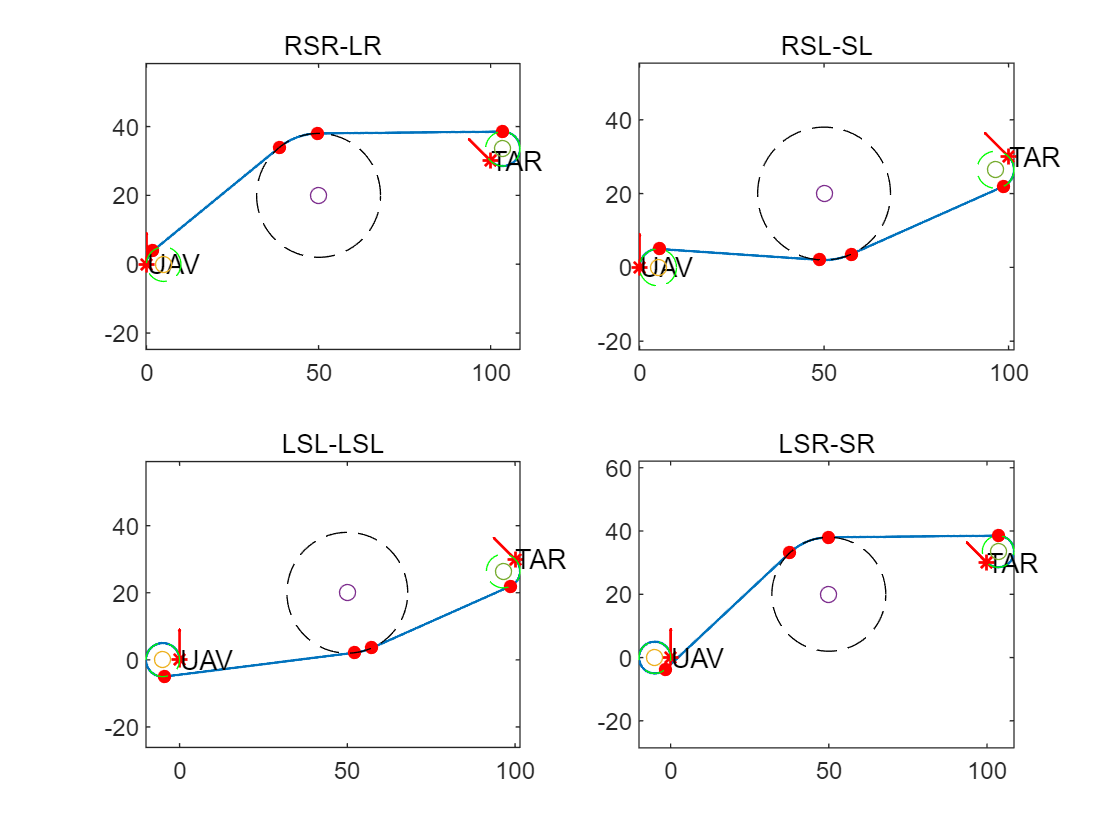

for i=1:length(param)
    subplot(2,2,i)
    DrawD_obs(param{i});
    title(titles(i))
end

figure('Name','默认');
subplot(2,2,1);    DrawD_obs(param{1});
    title(titles(1))
subplot(2,2,2);    DrawD_obs(param{2});
    title(titles(2))
subplot(2,2,3);    DrawD_obs(param{3});
    title(titles(3))
subplot(2,2,4);    DrawD_obs(param{4});
    title(titles(4))

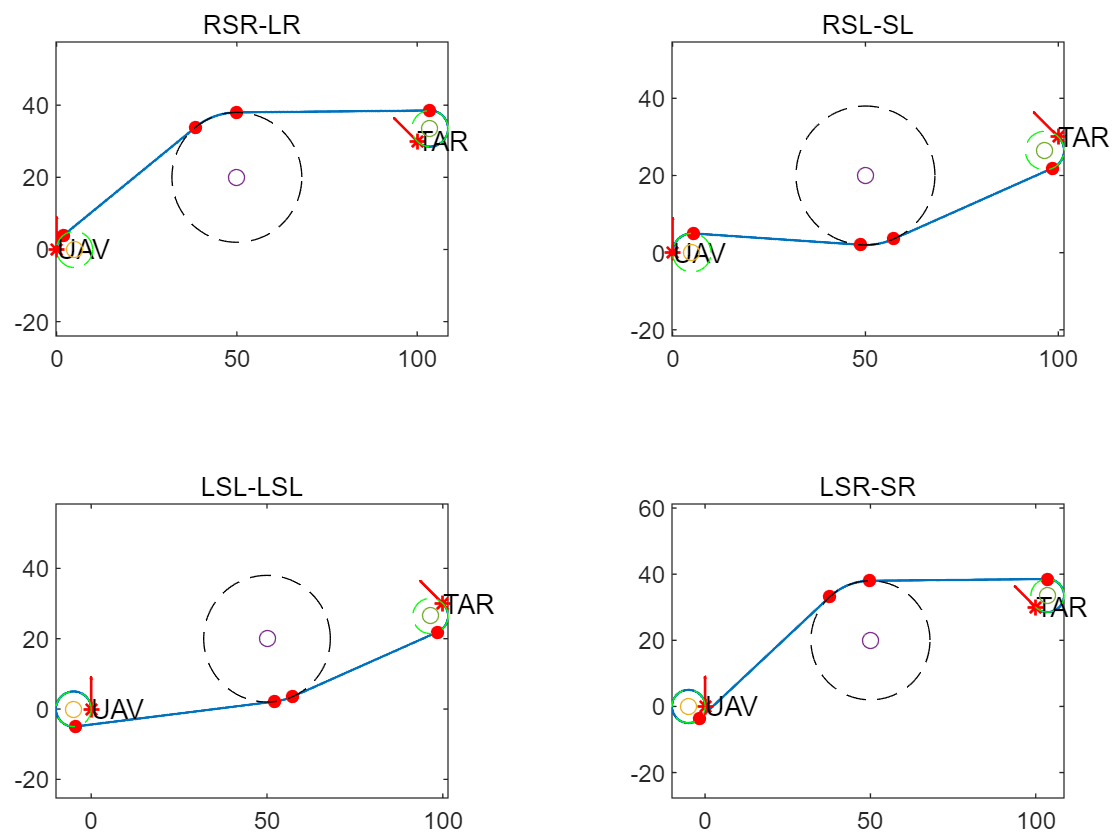


figure('Name','紧凑');
subplot('Position',[0.05 0.6 0.35 0.35]); DrawD_obs(param{1});
    title(titles(1))
subplot('Position',[0.6 0.6 0.35 0.35]); DrawD_obs(param{2});
    title(titles(2))
subplot('Position',[0.05 0.05 0.35 0.35]); DrawD_obs(param{3});
    title(titles(3))
subplot('Position',[0.6 0.05 0.35 0.35]); DrawD_obs(param{4});
    title(titles(4))




% 18,51,1080.5,860.5
% 11.5,44.5,1093.5,944
% 10 50
% 0 40
% 
% % set(gca, 'LooseInset', [0,0,0,0]);
% set(gca,'LooseInset',get(gca,'TightInset'))
